% HW 2.10 2.11 2.12
% Wanted to attempt 2.10 on MATLAB first
% Also did it on paper for practice.
% My answers for 2.11 are all done here on MATLAB
% 2.12 is completely on paper.

clearvars

syms h positive
syms w positive
syms m positive
syms x real

% a) Finding psi_2

% Momentum operator
pHat=@(f) -1i*h*diff(f,x) % <--- f can be anything

pHat = function_handle with value:
    @(f)-1i*h*diff(f,x)


% aPlus operator
aPlus=@(f) 1/sqrt(2*h*m*w)*((-1i*pHat(f))+(m*w*x*f))

aPlus = function_handle with value:
    @(f)1/sqrt(2*h*m*w)*((-1i*pHat(f))+(m*w*x*f))



A=((m*w)/(pi*h))^0.25

$$A = {\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}$$

psi_0=A*exp(((-m*w)/(2*h))*x^2)

$$psi\_0 = {\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}$$


% Use equation 2.68 NOT 2.62
psi_2=1/sqrt(factorial(2))*(aPlus(aPlus(psi_0)))

$$psi\_2 = \begin{array}{l} -\frac{h\,\left(\frac{\sqrt{2}\,\sqrt{m}\,\sqrt{w}\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}}{\sqrt{h}}-\frac{\sigma_{1}}{h^{3/2}}\right)-\frac{\sigma_{1}}{\sqrt{h}}}{2\,\sqrt{h}\,\sqrt{m}\,\sqrt{w}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2}\,m^{3/2}\,w^{3/2}\,x^{2}\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4} \end{array}$$

simplify(psi_2)

$$ans = -\frac{\sqrt{2}\,m^{1/4}\,w^{1/4}\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,\left(h-2\,m\,w\,x^{2}\right)}{2\,h^{5/4}\,\pi^{1/4}}$$

% ***DO NOT*** DO: (aPlus^2)*(psi_0).
% THE OPERATOR IS APPLIED TWICE TO PSI_0

% b) Sketching psi0, psi1, and psi2
psi_1=1/sqrt(factorial(1))*aPlus(psi_0)

$$psi\_1 = \frac{\sqrt{2}\,\sqrt{m}\,\sqrt{w}\,x\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}}{\sqrt{h}}$$

% NEED TO SUBSTITUTE SOME VALUE FOR M, W AND hbar
% psiGraph0=subs(psi_0, [m,w,h],[1,1,1.05457e-34])
% psiGraph1=subs(psi_1, [m,w,h],[1,1,1.05457e-34])
% psiGraph2=subs(psi_2, [m,w,h],[1,1,1.05457e-34])

psiGraph0=subs(psi_0, [m,w,h],[1,2,3])

$$psiGraph0 = {\mathrm{e}}^{-\frac{x^{2}}{3}}\,{\left(\frac{2}{3\,\pi }\right)}^{1/4}$$

psiGraph1=subs(psi_1, [m,w,h],[1,2,3])

$$psiGraph1 = \frac{2\,\sqrt{3}\,x\,{\mathrm{e}}^{-\frac{x^{2}}{3}}\,{\left(\frac{2}{3\,\pi }\right)}^{1/4}}{3}$$

psiGraph2=subs(psi_2, [m,w,h],[1,2,3])

$$psiGraph2 = -\frac{\sqrt{2}\,\sqrt{3}\,\left(2\,\sqrt{3}\,{\mathrm{e}}^{-\frac{x^{2}}{3}}\,{\left(\frac{2}{3\,\pi }\right)}^{1/4}-\frac{8\,\sqrt{3}\,x^{2}\,{\mathrm{e}}^{-\frac{x^{2}}{3}}\,{\left(\frac{2}{3\,\pi }\right)}^{1/4}}{3}\right)}{12}$$

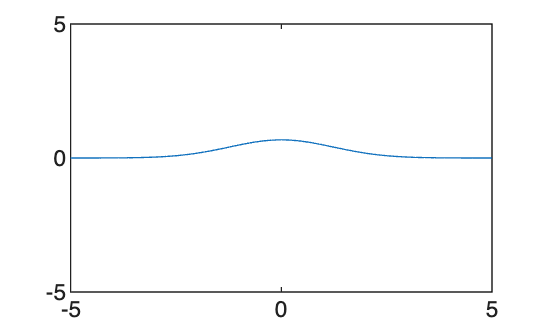


fplot(psiGraph0)
xlim([-5,5])
ylim([-5,5])

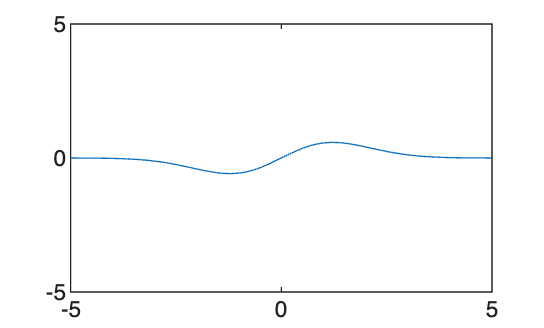

fplot(psiGraph1)
xlim([-5,5])
ylim([-5,5])

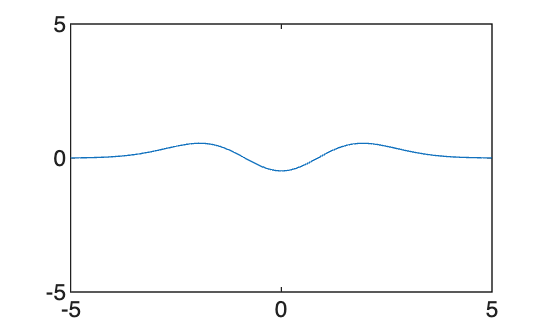

fplot(psiGraph2)
xlim([-5,5])
ylim([-5,5])


% c) Check orthogonality of psi0, psi1 and psi2
% NOTE: Remember the integral with psi_n multiplied
% by psi_m, and the Kronecker Delta

integral1=int(psi_0*psi_1,x,-inf,inf)

$$integral1 = 0$$

integral2=int(psi_0*psi_2,x,-inf,inf)

$$integral2 = 0$$

integral3=int(psi_1*psi_2,x,-inf,inf)

$$integral3 = 0$$

% All are zero because of orthogonality

2.11

% a) 
% Determine <x>, <p>, <x^2> and <p^2> for states psi0 and psi1
% psi0: use eq. 2.60
% psi1: use eq. 2.63

clearvars

syms h positive
syms m positive
syms w positive
syms x positive

A=((m*w)/(pi*h))^0.25

$$A = {\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}$$

psi_0=A*exp(((-m*w)/(2*h))*x^2)

$$psi\_0 = {\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}$$


pHat=@(f) -1i*h*diff(f,x)

pHat = function_handle with value:
    @(f)-1i*h*diff(f,x)


aPlus=@(f) (1/sqrt(2*h*m*w))*(-1i*pHat(f)+(m*w*x*f))

aPlus = function_handle with value:
    @(f)(1/sqrt(2*h*m*w))*(-1i*pHat(f)+(m*w*x*f))



psi_1=aPlus(psi_0)

$$psi\_1 = \frac{\sqrt{2}\,\sqrt{m}\,\sqrt{w}\,x\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}\,{\left(\frac{m\,w}{h\,\pi }\right)}^{1/4}}{\sqrt{h}}$$

simplify(psi_1)

$$ans = \frac{\sqrt{2}\,m^{3/4}\,w^{3/4}\,x\,{\mathrm{e}}^{-\frac{m\,w\,x^{2}}{2\,h}}}{h^{3/4}\,\pi^{1/4}}$$


% a) Expectation values for states
exp_x0=int(conj(psi_0)*x*psi_0,x,-inf,inf)

$$exp\_x0 = 0$$

exp_x2_0=int(conj(psi_0)*(x^2)*psi_0,x,-inf,inf)

$$exp\_x2\_0 = \frac{h}{2\,m\,w}$$

exp_p0=int(psi_0*(-1i*h)*diff(psi_0,x),x,-inf,inf)

$$exp\_p0 = 0$$

exp_p2_0=int(psi_0*((-1i*h)^2)*diff(psi_0,x,2),x,-inf,inf)

$$exp\_p2\_0 = \frac{h\,m\,w}{2}$$


exp_x1=int(conj(psi_1)*x*psi_1,x,-inf,inf)

$$exp\_x1 = 0$$

exp_x2_1=int(conj(psi_1)*(x^2)*psi_1,x,-inf,inf)

$$exp\_x2\_1 = \frac{3\,h}{2\,m\,w}$$

exp_p1=int(psi_1*(-1i*h)*diff(psi_1,x),x,-inf,inf)

$$exp\_p1 = 0$$

exp_p2_1=int(psi_1*((-1i*h)^2)*diff(psi_1,x,2),x,-inf,inf)

$$exp\_p2\_1 = \frac{3\,h\,m\,w}{2}$$


% b) Uncertainty principle 

standardDevx0=sqrt(exp_x2_0-(exp_x0^2))

$$standardDevx0 = \frac{\sqrt{2}\,\sqrt{h}}{2\,\sqrt{m}\,\sqrt{w}}$$

standardDevp0=sqrt(exp_p2_0-(exp_p0^2))

$$standardDevp0 = \frac{\sqrt{2}\,\sqrt{h}\,\sqrt{m}\,\sqrt{w}}{2}$$

uncertainty0=standardDevx0*standardDevp0==h/2

$$uncertainty0 = \frac{h}{2}=\frac{h}{2}$$

% satisfied
standardDevx1=sqrt(exp_x2_1-(exp_x1^2))

$$standardDevx1 = \frac{\sqrt{2}\,\sqrt{3}\,\sqrt{h}}{2\,\sqrt{m}\,\sqrt{w}}$$

standardDevp1=sqrt(exp_p2_1-(exp_p1^2))

$$standardDevp1 = \frac{\sqrt{2}\,\sqrt{3}\,\sqrt{h}\,\sqrt{m}\,\sqrt{w}}{2}$$

uncertainty1=standardDevx0*standardDevp0==h/2

$$uncertainty1 = \frac{h}{2}=\frac{h}{2}$$

% satisfied

% c) Expectation values of T and V for these states
% Note: Use example 2.5
% Expectation value for potential energy
exp_V0=0.5*m*(w^2)*exp_x2_0

$$exp\_V0 = \frac{h\,w}{4}$$

exp_V1=0.5*m*(w^2)*exp_x2_1

$$exp\_V1 = \frac{3\,h\,w}{4}$$

% Expectation value for kinetic energy
% Refer to eq. 1.37
% exp_T0=-(h^2)/(2*m)*int(conj(psi_0)*psi_0,x,-inf,inf)
% exp_T1=-(h^2)/(2*m)*int(conj(psi_1)*psi_1,x,-inf,inf)
exp_T0=(exp_p2_0)/(2*m)

$$exp\_T0 = \frac{h\,w}{4}$$

exp_T1=(exp_p2_1)/(2*m)

$$exp\_T1 = \frac{3\,h\,w}{4}$$